# Setup

clear

% %Get paths to models
% mlxpath = DirectoryHandlerSweep;
% pathTemp = split(mlxpath,'\');
% pathTemp = join(pathTemp(1:size(pathTemp,1)-1),'\');
% 
% simPath = pathTemp + "\Reproduce Land‘s Model\CombinedModel.slx";
% diffPath = pathTemp + "\Reproduce Land‘s Model\combinedDiffEquation.m";

%Set up time span and vector
dt = 0.01; %s
tend = 20; %s
t = 0:dt:tend;



%Setup Simulink Parameters
open_system('CombinedModel.slx')
set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
save_system('CombinedModel.slx')

# Sweep 1: PSM only and Input Frequency

## Constant simulation values

%Constant Gains
PSM = 0; %Just for crafting the sim_Set
VSM = 0;
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

## Simple sweep over small PSM, frequency range

PSM_Range = 1:2:21;
freq_range = 1:1:5;

## Sweep Function Call + plot full sweep grid

sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);

'GainFreq2ParamSweep' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Stability Parameter Sweep

Change the MATLAB current folder or add its folder to the MATLAB path.

plot_FullSweep(sweep_Results,PSM_Range,freq_range,"PSM")

As can be seen, the stability seems to be independent of input frequency (at least for the range chosen above).  We can more closely investigate the stability with

respect to the gain by sweeping only across the gain.

## Sweep across PSM gain only (frequency 1 Hz)

PSM_Range = 1:0.5:20;
freq_range = 1;

## Sweep Function Call + plot sweep grid

sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

From this we can see that for an input frequency of 1 Hz, instability occurs with a PSM somewhere between 15 and 16.  Let's more closely examine that interval.

## Sweep across PSM gain only: 15-16 (frequency 1 Hz)

PSM_Range = 15:0.05:16;
freq_range = 1;

## Sweep Function Call + plot sweep grid

sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

Looks like we need to increase the simulation time to get a clearer picture...

## Increase simulation time

%Set up time span and vector
dt = 0.01; %s
tend = 400; %s
t = 0:dt:tend;

set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
save_system(simName)

## Sweep across PSM gain only: 15-16 (frequency 1 Hz, tend = 400s)

PSM_Range = 15:0.05:16;
freq_range = 1;

## Sweep Function Call + plot sweep grid

sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

We can see that instability has an onset somewhere between PSM=15.7 and PSM=15.75.  Let's ensure that this is true at other frequencies as well.

## Sweep across PSM gain only: 15.7-15.75 (frequency 2-5 Hz, tend = 400s), plots

PSM_Range = [15.7 15.75];
freq_range = 2;
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

freq_range = 3;
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

freq_range = 4;
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

freq_range = 5;
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
plot_GainSweep(sweep_Results,PSM_Range,freq_range,"PSM")

We can see that the onset of instability occurs at the same location, regardless of input signal frequency.

Let's take a look at this in another way:

## Large Sweep with binary plot

%Set up time span and vector
dt = 0.01; %s
tend = 100; %s
t = 0:dt:tend;

set_param('CombinedModel','StartTime','0','StopTime',num2str(tend),'FixedStep',num2str(dt),'FastRestart','on')
save_system(simName)

%Ranges
PSM_Range = 1:.1:20;
freq_range = 1:.1:5;

%Simulate
sweep_Results = GainFreq2ParamSweep("PSM",PSM_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,PSM_Range,freq_range);

%Binary Plot
%Create Stable and Unstable series'
unstableBinary = unstable(:,1:2);
stableBinary = stable(:,1:2);

figure
scatter(stableBinary(:,1), stableBinary(:,2),'o')
hold on
scatter(unstableBinary(:,1), unstableBinary(:,2),'x')

# Sweep 2: VSM only and Input Frequency

## Constant simulation values

%Constant Gains
PSM = 0; 
VSM = 0; %Just for crafting the sim_Set
PSA = 0;
VSA = 0;

%Delay and zero-order hold time
delay = 0.1;

%Mystery Divisor
divisor = 1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;
vout_up = inf;
vout_low = -inf;

%Build sim_Set
sim_Set = struct('PSM',PSM,'VSM',VSM,'PSA',PSA,'VSA',VSA,'delay',delay,'divisor',divisor,'PSA_sat_up',PSA_sat_up,'PSA_sat_low',...
    PSA_sat_low,'VSA_sat_up',VSA_sat_up,'VSA_sat_low',VSA_sat_low,'PSM_sat_up',PSM_sat_up,'PSM_sat_low',PSM_sat_low,...
    'VSM_sat_up',VSM_sat_up,'VSM_sat_low',VSM_sat_low,'vout_up',vout_up,'vout_low',vout_low);

## Simple sweep over small VSM, frequency range

% VSM_Range = 1:2:21;
% freq_range = 1:1:5;

## Sweep Function Call + plot full sweep grid

% sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")

As can be seen, the break to instability occurs at much lower levels than PSM.  Let's adjust the range of gains.

## Sweep across VSM at lower gains

% VSM_Range = 0:.2:2;
% freq_range = 1:1:5;

## Sweep Function Call + plot sweep grid

% sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
% plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")

## Large Sweep with binary plot

%Ranges
VSM_Range = 0.1:.05:1.5;
freq_range = 0.1:.1:5;

%Simulate
sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
[unstable,stable] = stabChecker(sweep_Results,VSM_Range,freq_range);

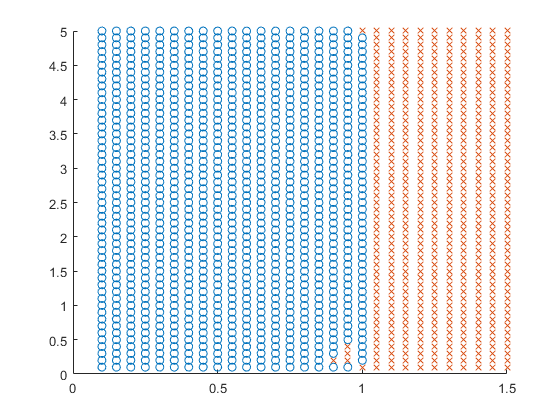


%Binary Plot
%Create Stable and Unstable series'
unstableBinary = unstable(:,1:2);
stableBinary = stable(:,1:2);

figure
scatter(stableBinary(:,1), stableBinary(:,2),'o')
hold on
scatter(unstableBinary(:,1), unstableBinary(:,2),'x')

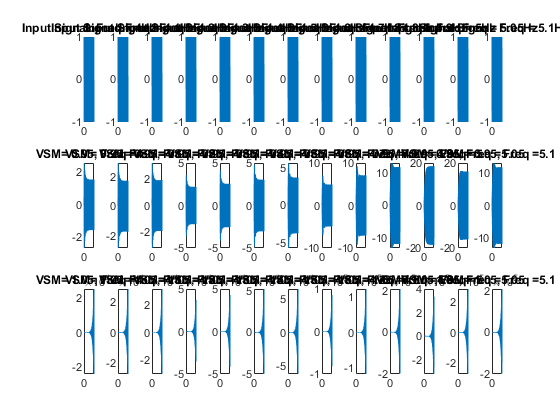

%Ranges
VSM_Range = [0.95 1.05];
freq_range = [4.0 4.1 4.2 4.3 4.4 4.5 4.6 4.7 4.8 4.9 5.0 5.05 5.1];

%Simulate
sweep_Results = GainFreq2ParamSweep("VSM",VSM_Range,freq_range,t,dt,sim_Set);
plot_FullSweep(sweep_Results,VSM_Range,freq_range,"VSM")